# Engine - Main Script

## Open Model and Run Simulation

mdl = "Engine_harness_model_power_split";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

% Load default parameters
Engine_harness_setup

% Set up external input signals
Engine_SignalBuilder = Engine_InputSignalBuilder;
inputPatterns = [
  "Input_Constant"
  "Step"
];
numSim = numel(inputPatterns);

% Create SimulationInput object for each simulation
%simIn(1:numSim) = Simulink.SimulationInput(mdl);  % error in R2022a.
simIn(1:numSim) = Simulink.SimulationInput(char(mdl));
for idx = 1 : numSim
  InpData = feval(inputPatterns(idx), Engine_SignalBuilder);
  simIn(idx) = setVariable(simIn(idx), "engineTestInput_Signals", InpData.Signals);
  simIn(idx) = setVariable(simIn(idx), "engineTestInput_Bus", InpData.Bus);
  simIn(idx) = setModelParameter(simIn(idx), "StopTime",num2str(InpData.Options.StopTime_s));
end

% Run simulations
simOut = sim(simIn, "UseFastRestart","on", "ShowProgress","on");

[08-Apr-2022 14:10:42] Running simulations...
[08-Apr-2022 14:10:45] Completed 1 of 2 simulation runs
[08-Apr-2022 14:10:46] Completed 2 of 2 simulation runs


## Simulation Results

Input_Constant


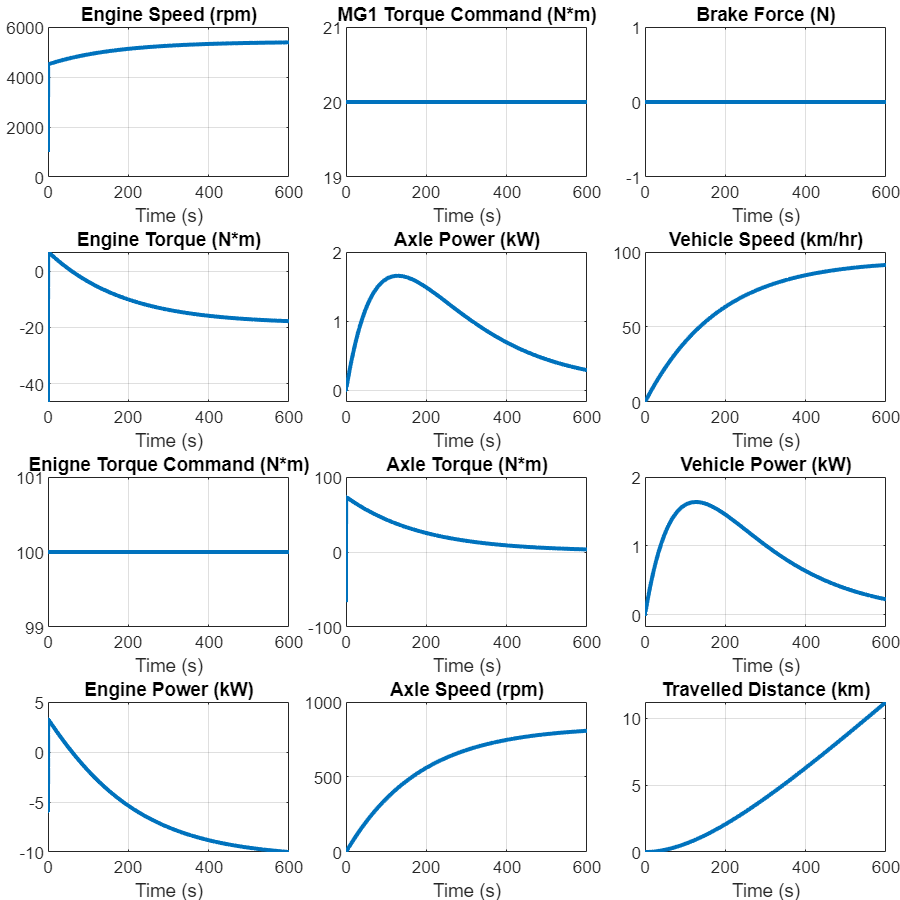

Step


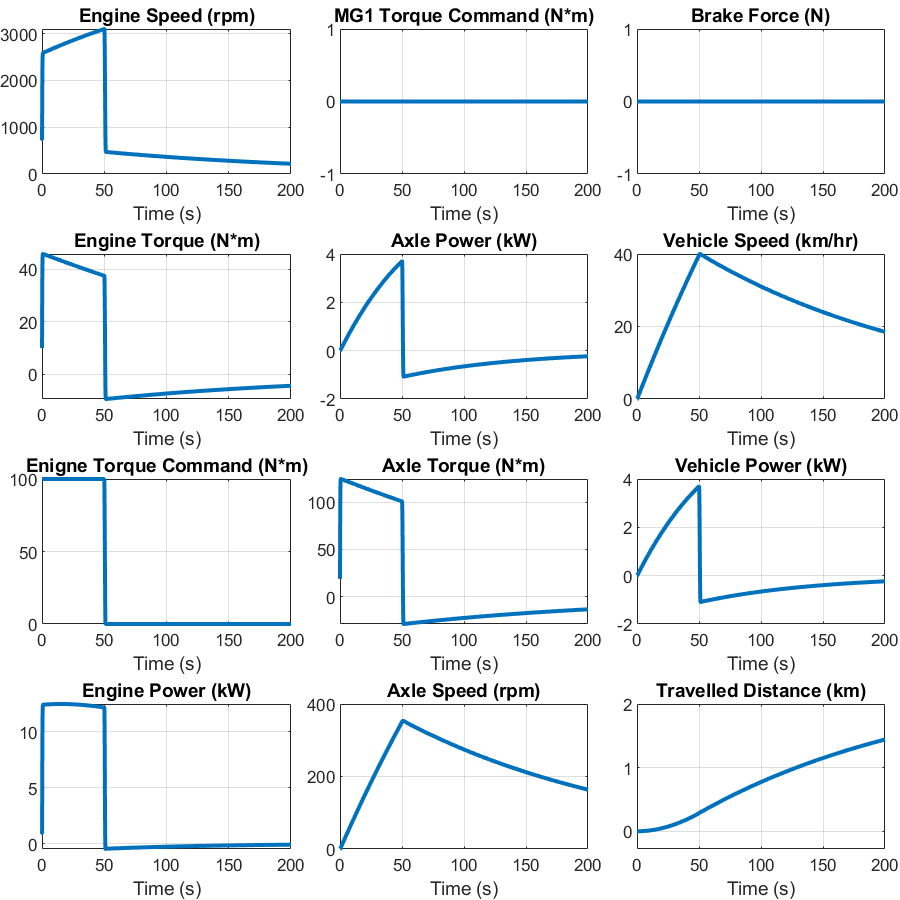

for idx = 1 : numSim
  disp(inputPatterns(idx))
  Engine_plot_results(simOut(idx).logsout)
end

*Copyright 2021-2022 The Mathworks, Inc.*